# Example: SLAM using LIDAR Toolbox

Ensure that this example is run in a separate MATLAB session from the Simulink Application. 

### **Background**

This example will receive LIDAR scans from the [Robot Simulink Application](matlab:open('./robot_app.slx')) (run in a separate MATLAB session), and generate a map using the LIDAR Toolbox. Once the map is sufficiently generated to your liking, it will be saved for future use. 

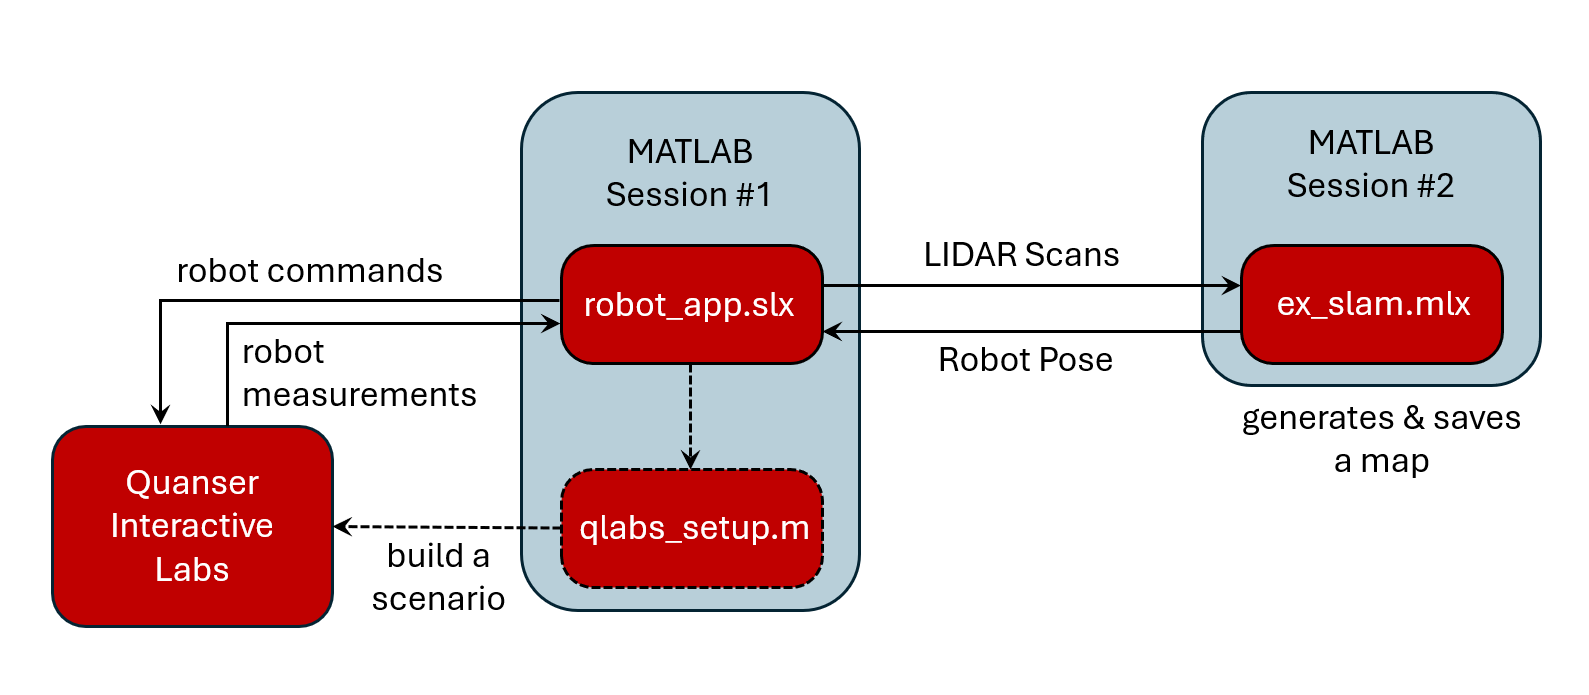

### Set up a Map object

Change the steady-state gain, $K$, and the time constant, $\tau$, to see how its affects the step response of a first-order system.

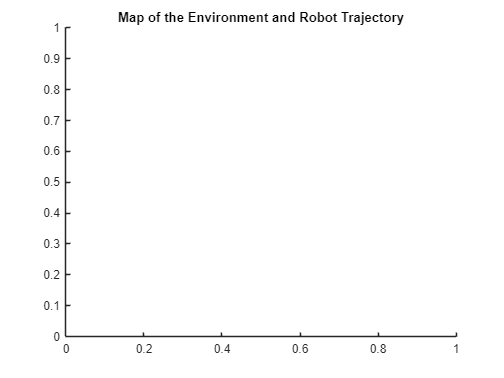

% Set up a LidarScanMap object
gridRes  =20;
maxRange =8;
map      = lidarscanmap(gridRes, maxRange); 

% Launch a figure to display the map.
hFigMap = figure;
% set(hFigMap,'Visible','on')
axMap   = axes(Parent=hFigMap);
title(axMap,"Map of the Environment and Robot Trajectory")

### Set up Additional Parameters

These parameters should not affect the performance of this example. 

step_size    = 0.10;         % time set 
t            = 0.0;          %
id           = 0;            % variable to hold 
pose         = [0, 0, 0];    % initial pose estimate
counter      = 0;            % incremement a counter for map rendering
totalScans   = 500;          % number of scans to hold in the map
totalTime    = 750;          % seconds
updateFactor = 30;           % pose graph optimization every N scans
renderFactor = 30;         % render every N scans

### Set up Stream communications 

This sets up the stream communications (using local TCPIP) with the [Robot Simulink Application](matlab:open('./robot_app.slx')) to exchange LIDAR scans and pose data.

% Quanser's Stream API
uri       = 'tcpip://localhost:18465';
stream    = quanser.communications.stream.connect(uri, false);

### Map Generation Loop

The code below is placed in a try/catch to correctly close the Stream connection under any condition. Check code comments for details. 

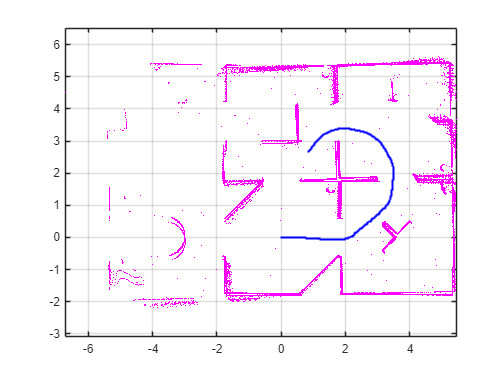


Server has closed the connection.



 Map saved, application terminating ...


Connection closed


try
    % Main loop
    while ~qc_get_key_state(27) % while Esc key not pressed  

        try
            % Send pose information back to the Robot Simulink Application
            stream.send_double_array(pose);
            stream.flush;

            % Receive Lidar data from the Robot Simulink Application
            % Note: this is a blocking stream and hence, handles timing
            value = stream.receive_double_array(420);
        catch
            fprintf(1, '\nServer has closed the connection.\n');
            break;
        end
        if isempty(value) % Simulink app was terminated...
            fprintf(1, '\nServer has closed the connection.\n');
            break;
        end
        
        % Create a lidarScan from the range/angle data received
        scan = lidarScan(value(1:210,1), value(211:420,1));

        % Build map until totalTime elapses or totalScans are exceeded
        if id < totalScans || t < totalTime

            % Attempt adding scan to map
            isScanAccepted = addScan(map, scan);
            if isScanAccepted % attempt successful
                id = id + 1;  % scan ID increment

                % Start Pose Graph optimization if atleast 10 scans have
                % been registered. Also do this for every 10th scan that is
                % added. 
                if id > updateFactor && mod(id, updateFactor) == 0

                    % Detect loop closure based on a decently large search
                    % radius but a tight threshold. We are looking for 1
                    % good match. 
                    [relPose, matchScanId, score] =             ...
                                        detectLoopClosure(map,  ...
                                            MatchThreshold=300, ...
                                            SearchRadius=15,     ...
                                            NumMatches=1);

                    % Check if a loop closure was found
                    if ~isempty(relPose)
                        % Check if the score was high enough
                        if score > 250
                            % Add loop closure to map object if relPose is estimated
                            addLoopClosure(map, matchScanId, id, relPose);

                            % Generate a poseGraph from the map and optimize it
                            pGraph = poseGraph(map);
                            updatedPGraph = optimizePoseGraph(pGraph);

                            % Add the updated scans back to the map 
                            optimizedScanPoses = nodeEstimates(updatedPGraph);
                            updateScanPoses(map, optimizedScanPoses);
                        end
                    end
                end            
                % Update the pose from the map
                pose = map.ScanAttributes{end, 'AbsolutePose'};
            end     
        else
            % Total scans exceeded and total time elapsed, exit loop
            break;
        end
        % Render the map at a slower rate to visualize SLAM
        if mod(counter, renderFactor) == 0
            map.show;
            drawnow;
        end
        t       = t + step_size;
        counter = counter + 1;
    end
    % Either, 
    %   1. escape key was pressed
    %   2. total time elapsed & total scans exceeded
    
    % Save the map for later use.
    save map.mat map   
    fprintf(1, '\n Map saved, application terminating ...\n');

    % Close the stream connection.
    stream.close;
    fprintf(1, 'Connection closed\n');
    
catch err
    % Error handling
    fprintf(1, '\n');
    fprintf(2, '\n%s.\n Error... shutting down the client...\n', err.message);
    stream.close;
    fprintf(1, 'Connection closed\n');
    rethrow(err);

end